# Calcolo Numerico con Laboratorio

# Prova in Laboratorio 

# 17 gennaio 2022

## Istruzioni

- Svolgere gli esercizi aggiungendo il codice nel file LIveScript con il testo degli esercizi oppure usando file di tipo Script.

- Se si usa il file Live Script le figure risultano automaticamente allegate.

- Se si lavora con file di tipo script, salvare le figure in formato .fig.

- Non usare il comando `input.`

- Eventuali commenti richiesti, devono essere scritti come testo nel file LiveScript.

- Caricare **tutti **i file usati (comprese le function prodotte durante le esercirazioni che servono per svolgere gli esercizi) e le figure richieste sul sito di elearning.

- Dopo aver aperto Matlab, dare il comando **diary** prima di cominciare a lavorare e ripetere questo comando tutte le volte che si riavvia Matlab. Il comando diary registra tutto quello che viene fatto durante la prova.

## Esercizio 1

Si consideri la funzione $f(x)=e^{-2x^2+1}\frac{\sin(2x-1)+2}{\cos(x)+1.2}$ per $x\in[-3,3]$.

Per `n=2:12`, eseguire le seguenti operazioni:

1. Interpolare la funzione nell'intervallo assegnato con i polinomi di grado `n`, costruiti usando $n+1$ nodi di Chebyshev e $n+1$ punti equidistanti .

2. Usando il comando subplot riportare 3 grafici contenenti rispettivamente: 

- la funzione e il polinomio interpolatore con nodi equidistanti;

- la funzione e il polinomio interpolatore con nodi di Chebyshev;

- la funzione e i due polinomi interpolatori.

3. Calcolare per ciascun valore di $n$ l'errore commesso usando i polinomi con nodi equidistanti e con nodi di Chebyshev.

4. Riportare gli errori per i due polinomi in uno stesso grafico in scala semilogaritmica.

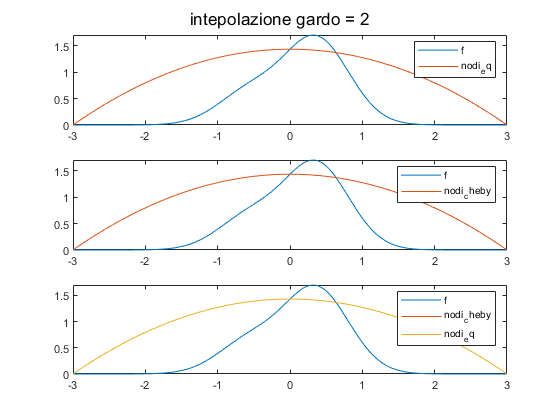

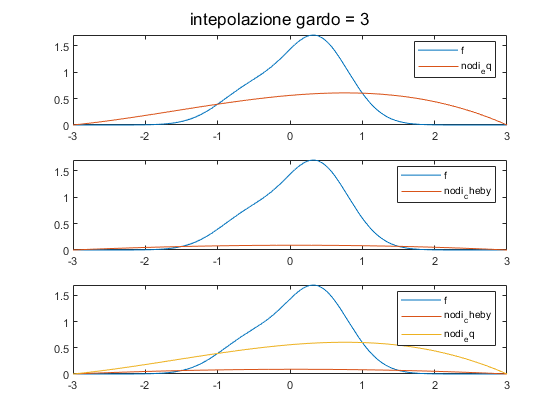

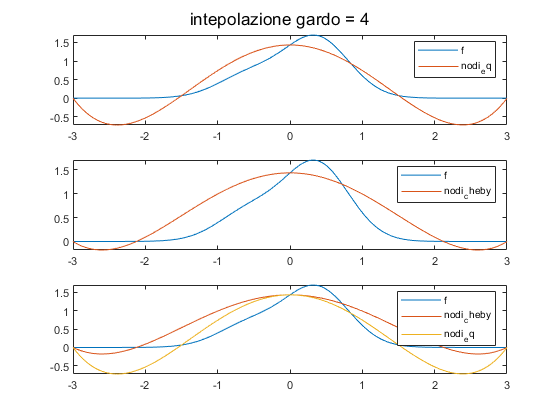

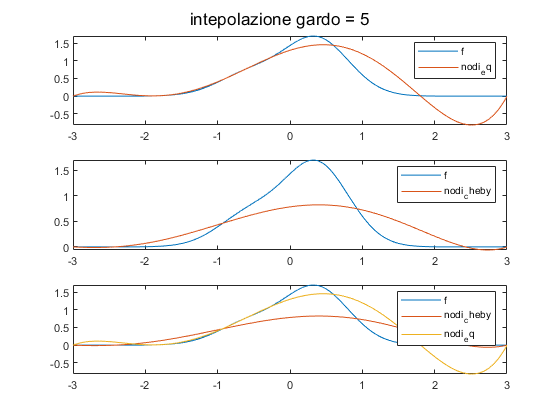

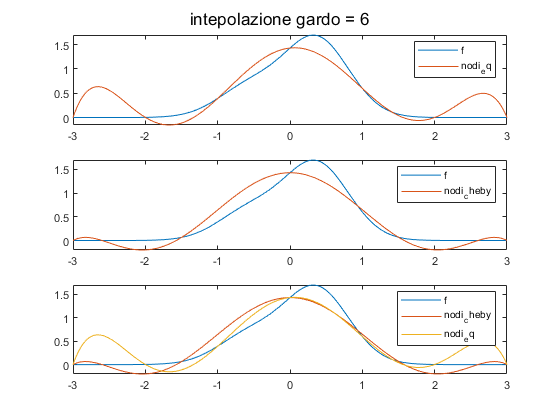

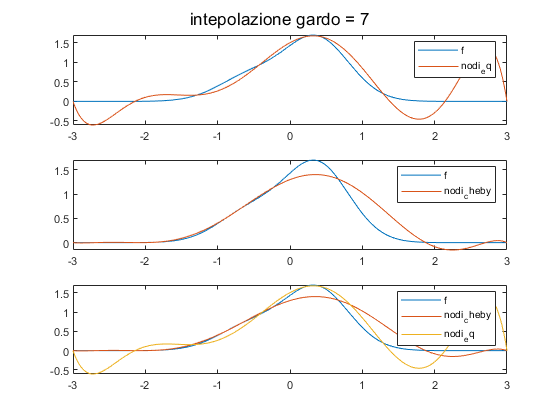

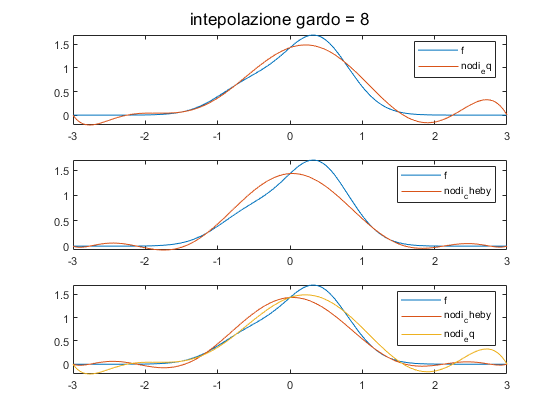

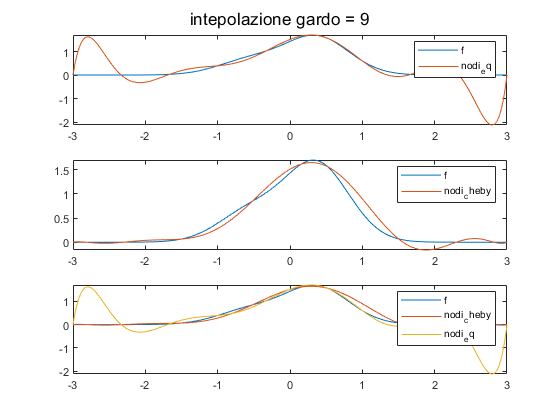

clear all
close all
f = @(x) exp(-2*x.^2+1).*(sin(2*x-1)+2)./(cos(x)+1.2); a=-3; b=3;

z = linspace(a,b,1000);
%se y è un valore check the funzione
N = 2:12;
err_eq =zeros(1,length(N));
err_cs =zeros(1,length(N));
for n = N
    
    %nodi eq
    xeq = linspace(a,b,n+1);
    yeq = f(xeq);
    ceq = polyfit(xeq,yeq,n);
    err_eq(n-1)=norm(f(z)-polyval(ceq,z),inf);
    %
    [ccs,xcs,y,err] = chebyshev(f,a,b,n);
    err_cs(n-1)=norm(f(z)-polyval(ccs,z),inf);
    figure
    sgtitle("intepolazione gardo = "+n)
    subplot(3,1,1)
    fplot(f,[a b])
    hold on
    plot(z,polyval(ceq,z))
    legend("f","nodi_eq")
    
    subplot(3,1,2)
    fplot(f,[a b])
    hold on
    plot(z,polyval(ccs,z))
    legend("f","nodi_cheby")
    
    subplot(3,1,3)
    fplot(f,[a b])
    hold on
    plot(z,polyval(ccs,z))
    plot(z,polyval(ceq,z))
    legend("f","nodi_cheby","nodi_eq")
    
end

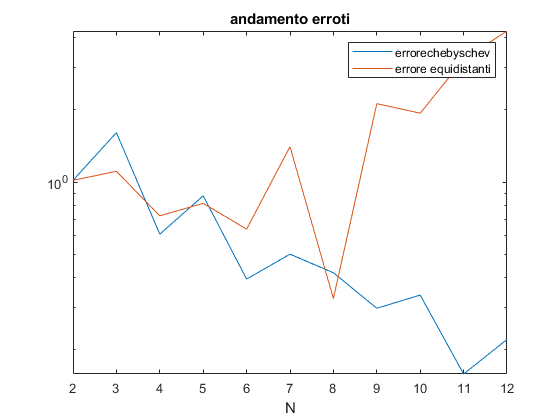

figure
semilogy(N,err_cs,N,err_eq)
title("andamento errori")
xlabel N
legend("errorechebyschev","errore equidistanti")

Esercizio 2

Usare la function `newton `e il solutore di Matlab `fzero `per calcolare gli zeri della seguente funzione:

$f(x)=2\arctan(x)+\sin(2x)(x^2-1)-\cos(x)+1$ per $x\in[-\pi,\pi]$.

Usare i seguenti dati iniziali `x0=[-1 1 2 3],`e porre `toll=1e-10` e `nmax=50 `nella function `newton.`

- Fare un grafico della funzione e riportare sul grafico tutti gli zeri calcolati con i due metodi (marcare gli zeri di Newton con * e quelli di fzero con o).

- Per ciascun dato iniziale riportare la successione generata con il metodo di Newton.

- Riportare in un unico grafico in scala semilogaritmica la differenza fra due iterate successive ottenute con il metodo di Newton e commentare il risultato.

- Per visualizzare meglio quanto ottenuto in corrispondenza dei primi due dati iniziali, fare un ingrandimento della funzione con gli zeri corrispondenti nell'intervallo $[-0.3,0.3]$. 

- Osservando il grafico della soluzione, qual è la molteplicità degli zeri?

- `newton` ed `fzero `convergono allo stesso valore?

- Qual è l'ordine di convergenza del metodo di Newton in ciascun caso?  

Rispondere agli ultimi tre punti utilizzando il file LiveScript del compito oppure aggiungendo dei commenti sul file di tipo Script.

clear all
close all
syms x
f = 2*atan(x)+sin(2*x).*(x.^2-1)-cos(x)+1; a=-pi;b=pi;a1=-0.3;b1=0.3;
X0=[-1 1 2 3];
toll = 1e-10;
Nmax = 50;
figure(10)
fplot(matlabFunction(f),[a b])
hold on
plot([a b],[0 0],'--')
figure(40)
fplot(matlabFunction(f),[a1 b1])
hold on
plot([a1 b1],[0 0],'--')


for i=1:length(X0)
    [zero,fz,iter,xk] = newton(f,X0(i),toll,Nmax);
    ordineConv(matlabFunction(diff(f)),X0(i),zero)    
    figure(30)
    semilogy(abs(xk(1:end-1)-xk(2:end)))
    hold on
    figure(20)
    plot(xk)
    hold on
    figure(10)
    plot(zero,fz,'*b')
    hold on    
    [zero1,fval,exitflag,output]=fzero(matlabFunction(f),X0(i));
    figure(10)
    plot(zero1,fval,'or')
    hold on
    if(X0(i) == X0(1) || X0(i) == X0(2))
        figure(40)
        plot(zero,fz,'*b')
        hold on
        plot(zero1,fval,'or')
    end
end

per x0=-1 si trova uno zero:-0.19002 e si ha uno zero singolo
ordine di convergenza 2


per x0=1 si trova uno zero:3.1208e-10 e si ha uno zero doppio
ordine di convergenza 1


per x0=2 si trova uno zero:2.2425 e si ha uno zero singolo
ordine di convergenza 2


per x0=3 si trova uno zero:2.7893 e si ha uno zero singolo
ordine di convergenza 2


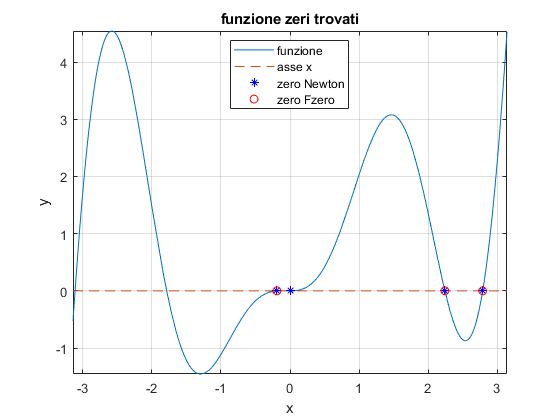


figure(10)
legend("funzione","asse x","zero Newton","zero Fzero","Location","best")
title("funzione zeri trovati")
xlabel x
ylabel y
grid on

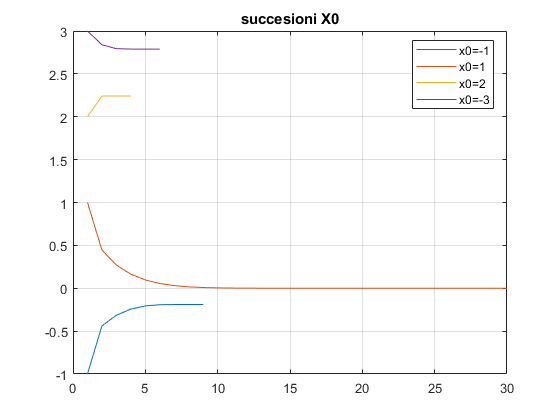

figure(20)
legend("x0=-1","x0=1","x0=2","x0=-3","Location","best")
title("succesioni X0")
grid on

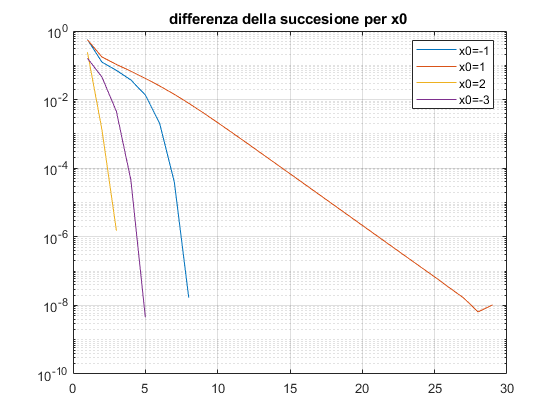

figure(30)
legend("x0=-1","x0=1","x0=2","x0=-3","Location","best")
title("differenza della succesione per x0 ")
grid on

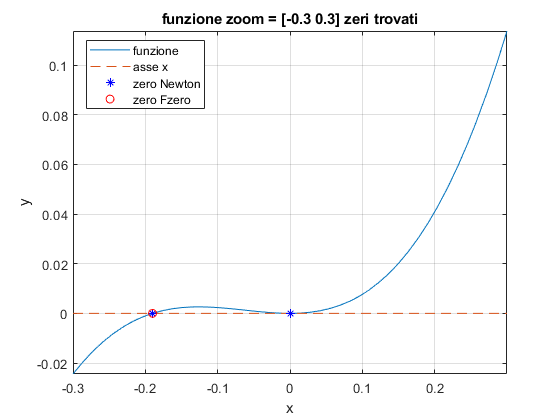

figure(40)
legend("funzione","asse x","zero Newton","zero Fzero","Location","best")
title("funzione zoom = [-0.3 0.3] zeri trovati")
xlabel x
ylabel y
grid on

**5-7)** si hanno tutti zeri singoli con ordine di convergenza 2 mentre per x0 = 1 si trova uno zero doppio con ordine di convergenza paria a 1.

**6)** fzero e newton non riescono a trovare gli stessi zeri della funzione infatti fzero non riesce a trovare lo zero in x=0 questo è dovuto al dovuto all'utilizzo di due metodi differenti 

## Esercizio 3

Consideriamo il seguente sistema di equazioni differenziali ordinarie:


$$\left\{
\begin{array}{l}
y_1'=a(y_2-y_1)\\
y_2'=ry_1-y_2-y_1y_3\\
y_3'=-by_3+y_1y_2
\end{array}
\right.

$$


dove $a$, $b$ e $r$ sono delle costanti positive legate a quantità fisiche. Questo sistema rappresenta un modello semplificato della turbolenza atmosferica la cui derivazione può essere così sintetizzata: una cella bidimensionale verticale di aria viene riscaldata dal basso e raffreddata dall'alto e il risultante movimento viene descritto da un sistema di equazioni alle derivate parziali. Sviluppando in serie le variabili e approssimandole opportunamente si giunge al sistema dato. La variabile $y_1$ rappresenta il tasso di ricircolazione convettiva, $y_2$ e $y_3$  misurano la variazione di temperatura lungo l'orizzontale e lungo la verticale rispettivamente. 

Questo sistema presenta soluzioni che per alcuni dati iniziali hanno un andamento caotico. Inoltre il sistema ha 3 punti di equilibrio: $O=(0,0,0)$, $P_1=(c,c,r-1)$ e $P_2=(-c,-c,r-1)$ dove $c=\sqrt{b(r-1)}$. Posto $r_{rc}=a(a+b+3)/(a-b-1)$, $P_1$ e $P_2$ sono asintoticamente stabili se $r<r_{rc}$ e instabili se $r>r_{rc}$.

Posto $a=10$, $b=8/3$ e `toll=1e-10 `$r=70$, verificare se la soluzione deve risultare stabile oppure no. Calcolare con `ode45 `la soluzione del sistema nell'intervallo $[0,20]$ con la condizione iniziale $y_0=(1,1,1)$.

Riportare le tre componenti in un grafico in funzione del tempo e successivamente usare il comando `plot3` per graficare l'orbita ottenuta. Nel grafico dell'orbita marcare anche i punti di equilibrio.

Calcolare la soluzione nello stesso intervallo di tempo ponendo $r=r_{rc}-1$ e con i seguenti dati iniziali $y_0=(1,1,1)$ e $y_0=(-1,1,1)$e riportare i risultati in un grafico in funzione del tempo e l'orbita corrispondente insieme ai punti di equilibrio. Si osserva che a seconda del dato iniziale le orbite si addensano attorno a $P_1$ o a $P_2$.

clear all
close all
a=10;b=8/3;toll=1e-10;r=70;
c = sqrt(b*(r-1));
rrc = a*(a+b+3)/(a-b-1);
f = @(t,y) [a*(y(2)-y(1));r*y(1)-y(2)-y(1).*y(3);-b.*y(3)+y(1).*y(2)];
O=[0 0 0];
p1 = [c c r-1];
p2 = [-c -c r-1];
if(r<rrc)
    disp("asistoticamente stabile")
else
    disp("instabile")
end

instabile


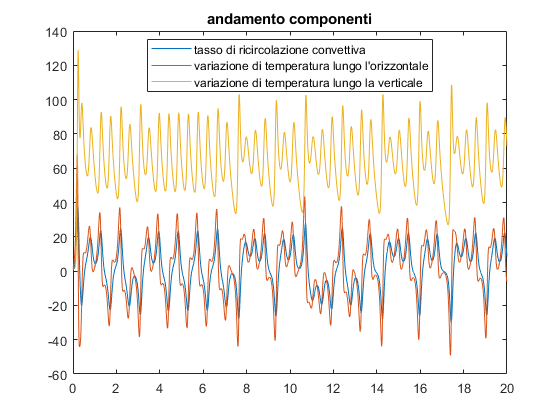


intervallo = [0 20];
y0 = [1 1 1];
opt = odeset("RelTol",toll);
[t,u]=ode45(f,intervallo,y0,opt);
plot(t,u(:,1),t,u(:,2),t,u(:,3))
title("andamento componenti")
legend("tasso di ricircolazione convettiva", ...
    "variazione di temperatura lungo l'orizzontale", ...
    "variazione di temperatura lungo la verticale", ...
    "location","best")

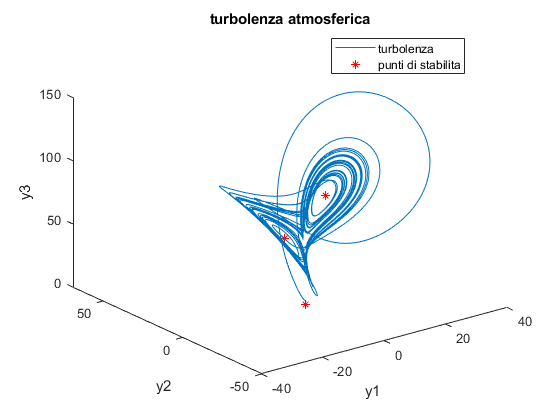


plot3(u(:,1),u(:,2),u(:,3))
title("turbolenza atmosferica")
xlabel y1
ylabel y2
zlabel y3
hold on
plot3([O(1),p1(1),p2(1)],[O(2),p1(2),p2(2)],[O(3),p1(3),p2(3)],'*r')
legend("turbolenza","punti di stabilita","location","best")
hold off

clear all
a=10;b=8/3;toll=1e-10;

rrc = a*(a+b+3)/(a-b-1)

rrc = 24.7368

r=rrc-1;
c = sqrt(b*(r-1));
f = @(t,y) [a*(y(2)-y(1));r*y(1)-y(2)-y(1).*y(3);-b.*y(3)+y(1).*y(2)];
O=[0 0 0];
p1 = [c c r-1];
p2 = [-c -c r-1];
opt = odeset("RelTol",toll);
if(r<rrc)
    disp("asistoticamente stabile")
else
    disp("instabile")
end

asistoticamente stabile


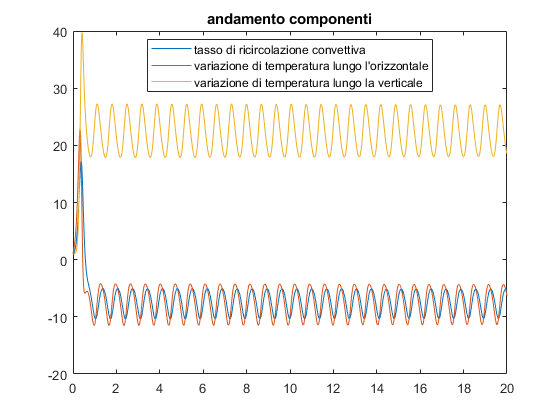


y0 = [1 1 1];
[t,u]=ode45(f,[0 20],y0,opt);
figure
plot(t,u(:,1),t,u(:,2),t,u(:,3))
title("andamento componenti")
legend("tasso di ricircolazione convettiva", ...
    "variazione di temperatura lungo l'orizzontale", ...
    "variazione di temperatura lungo la verticale", ...
    "location","best")

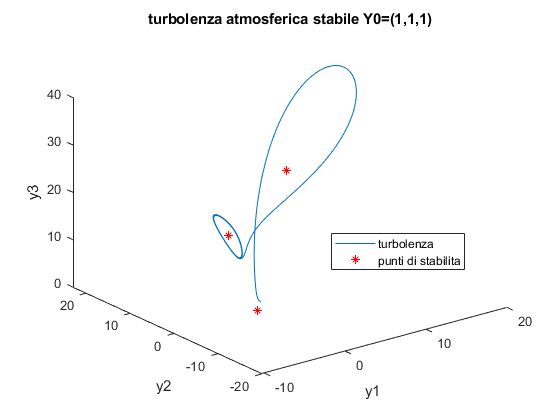

figure
plot3(u(:,1),u(:,2),u(:,3))
title("turbolenza atmosferica stabile Y0=(1,1,1)")
xlabel y1
ylabel y2
zlabel y3
hold on
plot3([O(1),p1(1),p2(1)],[O(2),p1(2),p2(2)],[O(3),p1(3),p2(3)],'*r')
legend("turbolenza","punti di stabilita","location","best")
hold off

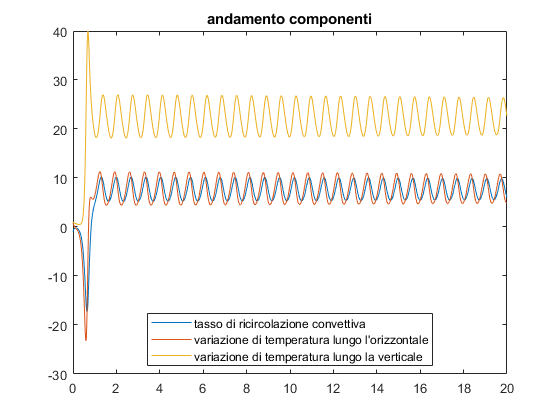


y0 = [-1 1 1];
[t,u]=ode45(f,[0 20],y0,opt);
plot(t,u(:,1),t,u(:,2),t,u(:,3))
title("andamento componenti")
legend("tasso di ricircolazione convettiva", ...
    "variazione di temperatura lungo l'orizzontale", ...
    "variazione di temperatura lungo la verticale", ...
    "location","best")

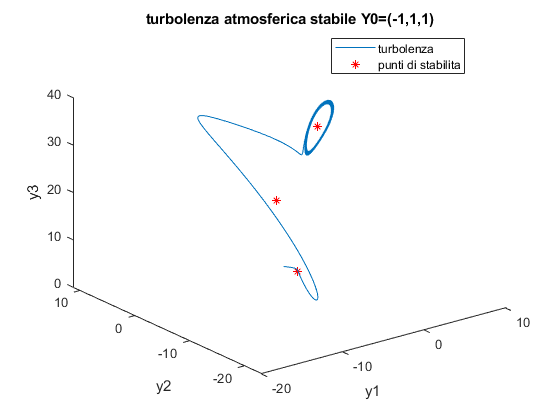

plot3(u(:,1),u(:,2),u(:,3))
title("turbolenza atmosferica stabile Y0=(-1,1,1)")
xlabel y1
ylabel y2
zlabel y3
hold on
plot3([O(1),p1(1),p2(1)],[O(2),p1(2),p2(2)],[O(3),p1(3),p2(3)],'*r')
legend("turbolenza","punti di stabilita","location","best")
hold off

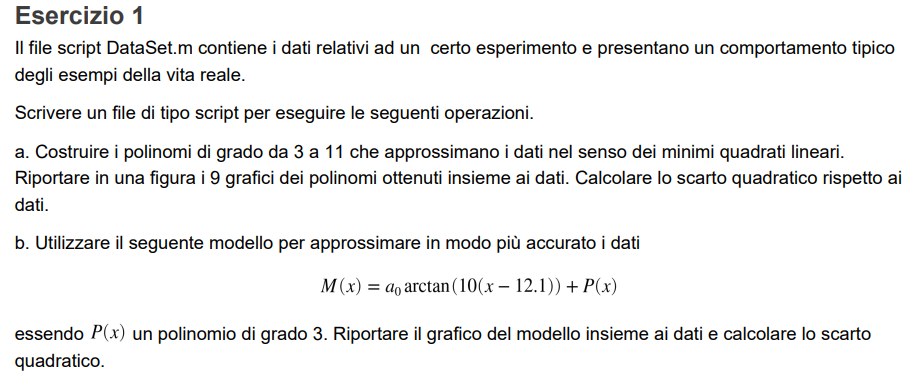

clear all
close all
DataSet

z=linspace(x(1),x(end),101);
figure
figure
sgtitle("Polinomi")

for n=3:11 
    [c,non,mu] = polyfit(x,y,n);
    sse = norm(y-polyval(c,x,[],mu))^2;
    disp("scarto quadratico per N = "+n+" => SSE = "+sse)
    subplot(3,3,n-2)
    plot(x,y,'xk')
    hold on
    plot(z,polyval(c,z,[],mu))
    title("grado N = "+n)
    grid on
    xlabel x
    ylabel y
    legend("dati","poly","location","best")
end

scarto quadratico per N = 3 => SSE = 13.1169


scarto quadratico per N = 4 => SSE = 12.4614


scarto quadratico per N = 5 => SSE = 7.1885


scarto quadratico per N = 6 => SSE = 6.3532


scarto quadratico per N = 7 => SSE = 4.1286


scarto quadratico per N = 8 => SSE = 3.3585


scarto quadratico per N = 9 => SSE = 2.3866


scarto quadratico per N = 10 => SSE = 1.8388


scarto quadratico per N = 11 => SSE = 1.3876




B=[ atan(10*(x-12.1)) x.^3 x.^2 x.^1 ones(size(x))];

alfa = B\y;
M = @(x) alfa(1)*atan(10*(x-12.1))+alfa(2)*x.^3+alfa(3)*x.^2+alfa(4)*x+alfa(5);
figure
plot(x,y,'xk')
hold on
fplot(M,[x(1) x(end)])
title("Modello e dati")
grid on
xlabel x
ylabel y
legend("dati","modello","location","best")
sse = norm(y-M(x))^2;
disp("scarto quadratico per il modello => SSE = "+sse)

scarto quadratico per il modello => SSE = 0.045343



%cftool(x,y)
cftool modello.sfit

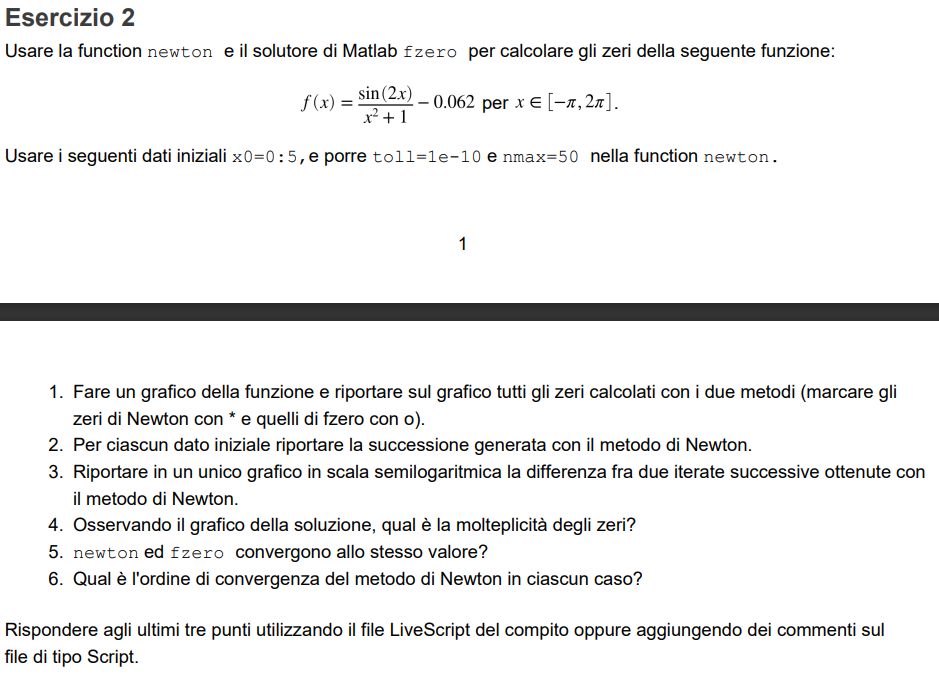

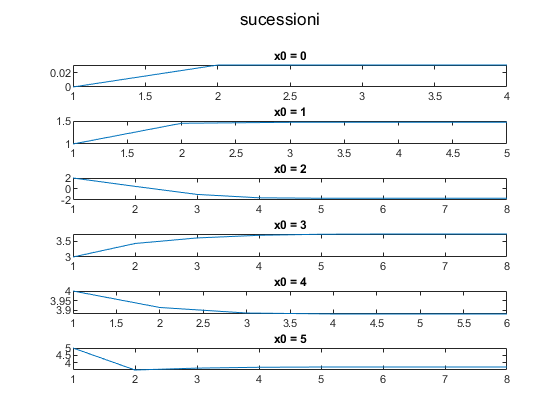

per x0=0 si trova uno zero:0.03105 e si ha uno zero singolo
ordine di convergenza 2


per x0=1 si trova uno zero:1.472 e si ha uno zero singolo
ordine di convergenza 2


per x0=2 si trova uno zero:-1.6917 e si ha uno zero singolo
ordine di convergenza 2


per x0=3 si trova uno zero:3.7341 e si ha uno zero singolo
ordine di convergenza 2


per x0=4 si trova uno zero:3.8807 e si ha uno zero singolo
ordine di convergenza 2


per x0=5 si trova uno zero:3.7341 e si ha uno zero singolo
ordine di convergenza 2


clear all
close all
toll = 1e-10;
nmax = 50;
syms x
f = (sin(2*x)./(x.^2+1))-0.062;
a =-pi;
b = 2*pi;
F=matlabFunction(f);
figure(10)
fplot(F,[a b])
hold on
plot([a b],[0 0],'--')
leg = ["funzione" "asse x"];
figure(20)
sgtitle("sucessioni")
leg2=[];
zeron = ones(1,length(0:5));
zerof = ones(1,length(0:5));
for x0= 0:5
    [zero,fz,iter,xk]=newton(f,x0,toll,nmax);
    ordineConv(matlabFunction(diff(f)),x0,zero)
    zeron(x0+1)=zero;
    figure(30)
    dif = abs(xk(1:end-1)-xk(2:end));
    semilogy(dif)
    hold on
    leg2=[leg2 "x0="+x0];
    
    figure(20)
    subplot(6,1,x0+1)
    plot(xk)
    title("x0 = "+x0)
    if(fz<1)
         figure(10)
         plot(zero,fz,'*k')
         hold on
    end
    
    [zero1,fval,flag,out]=fzero(F,x0);
    zerof(x0+1)=zero1;
    if(fz<1)
         figure(10)
         plot(zero1,fval,'or')
         hold on   
    end
end

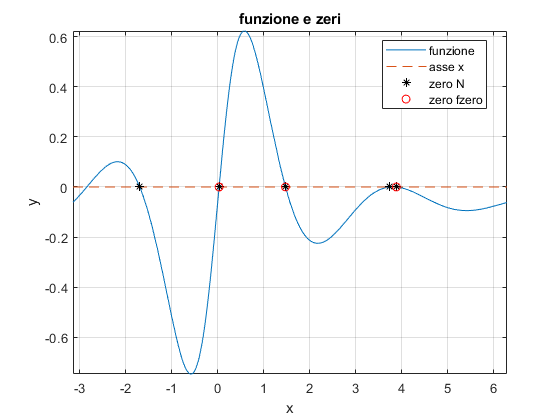

figure(10)
title("funzione e zeri")
grid on
leg = [leg "zero N"];
leg = [leg "zero fzero"];
legend(leg,"Location","best")
xlabel x
ylabel y

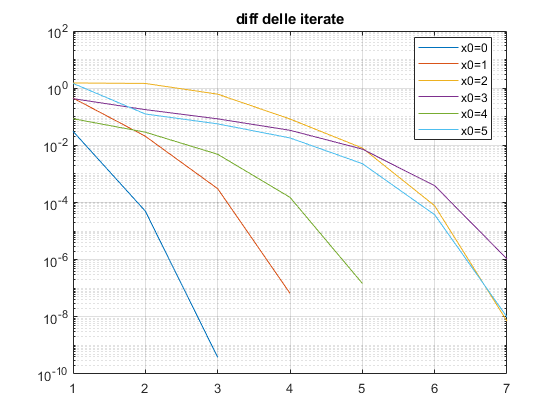

figure(30)
title("diff delle iterate")
legend(leg2,"Location","best")
grid on

x0=0:5;
table(x0',zeron',zerof','VariableNames',{'x0','zero Newton','zero fzero'})

ans = 6×3 table
    x0    zero Newton    zero fzero
    __    ___________    __________
    0       0.03105       0.03105  
    1         1.472         1.472  
    2       -1.6917         1.472  
    3        3.7341        3.8807  
    4        3.8807        3.8807  
    5        3.7341        3.8807  

nell'esercizio in questione la function fzero non riesce a trovare due zeri rispetto  alla funzione newton.

Gli zeri in questione sono in x = -1.69 e in x = 3.73 questo è dovuto dal fatto che le funzioni utilizzano differenti algoritmi di ricerca.

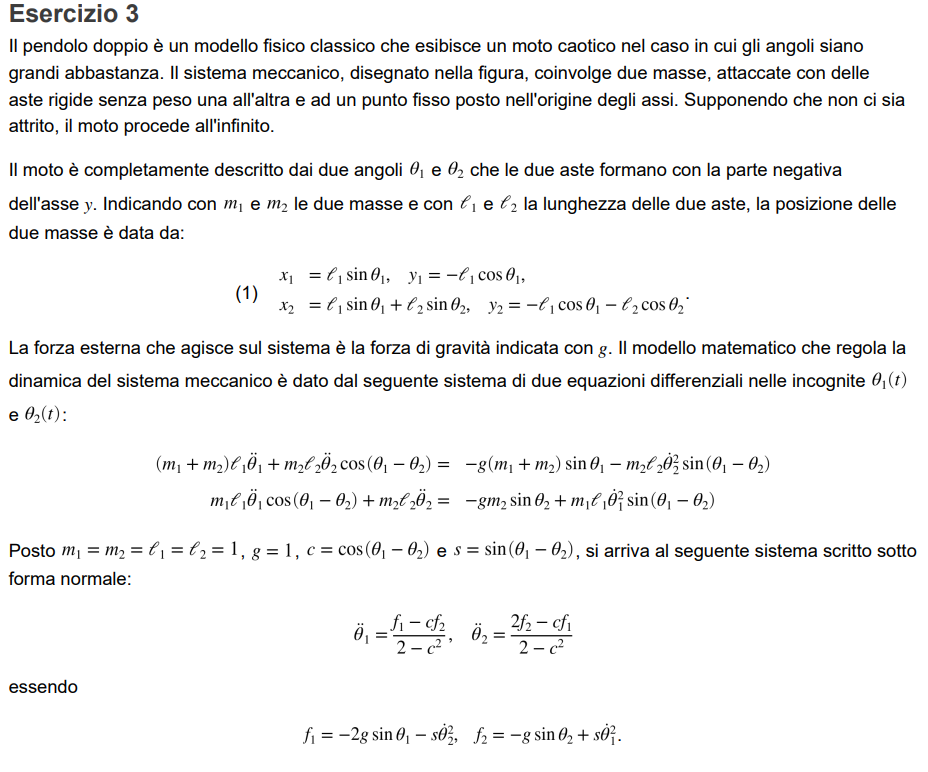

z1 = teta1      =>     z1' = z2

z2 = teta1'     =>     z2'' =  teta1''

z3 = teta2      =>     z3' = z4

z4 = teta2'     =>     z4' = teta2''

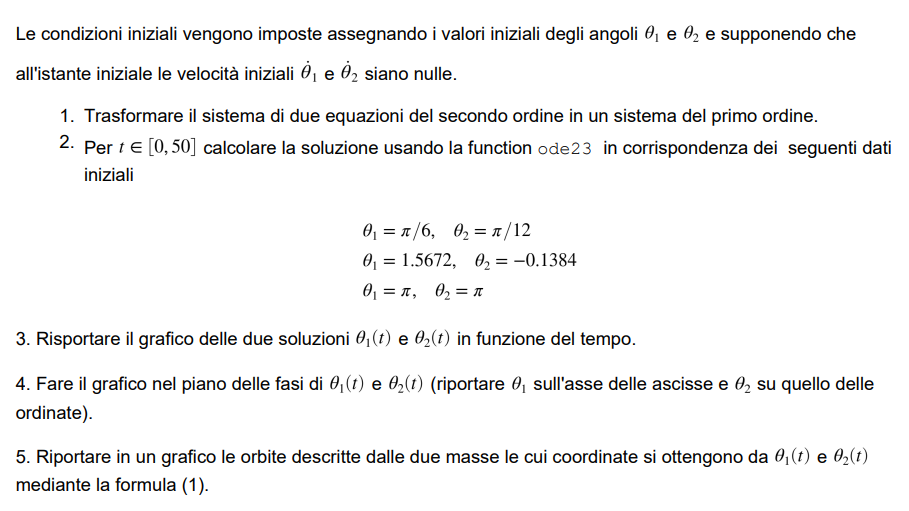

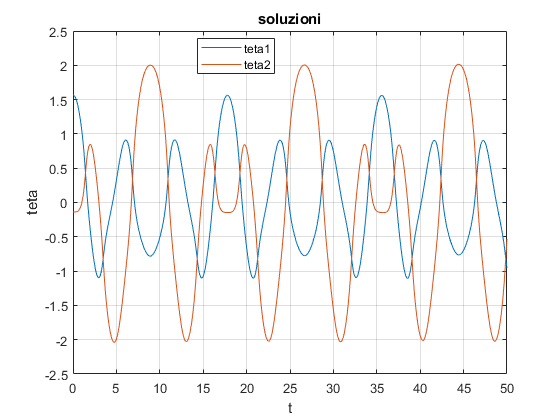


clear all
close all
m = 1; l = 1; g = 1;
t = [0 50];
%y0=[pi/6 0 pi/12 0];
y0=[1.5672 0 -0.1384 0];
%y0=[pi 0 pi 0];

c = @(t,z) cos(z(1)-z(3));
s = @(t,z) sin(z(1)-z(3));
f1 =@(t,z) -2.*sin(z(1)) - s(t,z).*(z(4)).^2;
f2 =@(t,z) -sin(z(3)) + s(t,z)*(z(2)).^2;
f = @(t,z) [z(2);(f1(t,z)-c(t,z).*f2(t,z))./(2-c(t,z).^2);z(4); (2.*f2(t,z)-c(t,z).*f1(t,z))./(2-c(t,z).^2)];
[t,u]=ode23(f,t,y0);
plot(t,u(:,1))
hold on
plot(t,u(:,3))
title soluzioni
xlabel t
ylabel teta
grid on
legend("teta1","teta2","Location","best")
hold off

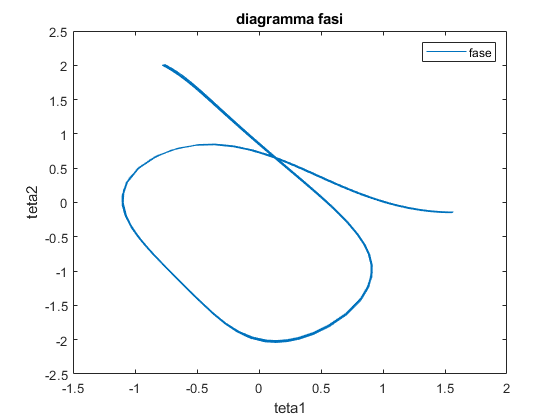

plot(u(:,1),u(:,3))
xlabel teta1
ylabel teta2
legend("fase")
title("diagramma fasi")

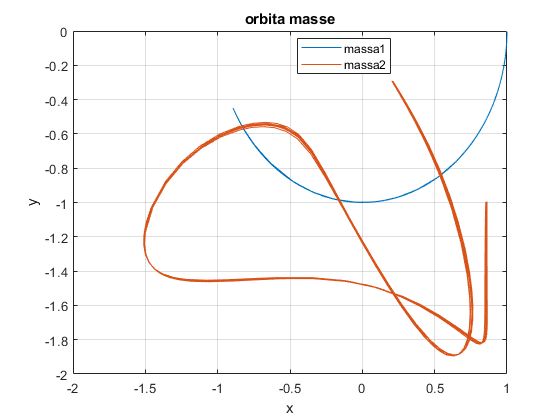


plot(sin(u(:,1)),-cos(u(:,1)))
title("orbita masse")
xlabel x
ylabel y
grid on
hold on
plot(sin(u(:,1))+sin(u(:,3)),-cos(u(:,1))-cos(u(:,3)))
legend("massa1","massa2","Location","best")

# Calcolo Numerico con Laboratorio

# Prova in Laboratorio 

# 11 aprile 2022

## Istruzioni

- Svolgere gli esercizi aggiungendo il codice nel file LIveScript con il testo degli esercizi oppure usando file di tipo Script.

- Se si usa il file Live Script le figure risultano automaticamente allegate.

- Se si lavora con file di tipo script, salvare le figure in formato .fig.

- Non usare il comando `input.`

- Eventuali commenti richiesti, devono essere scritti come testo nel file LiveScript.

- Caricare **tutti **i file usati (comprese le function prodotte durante le esercirazioni che servono per svolgere gli esercizi) e le figure richieste sul sito di elearning.

- Dopo aver aperto Matlab, dare il comando **diary** prima di cominciare a lavorare e ripetere questo comando tutte le volte che si riavvia Matlab. Il comando diary registra tutto quello che viene fatto durante la prova.

## Esercizio 1

Il file `dati_20220411.mat `contiene le osservate di una certa quantità nell'intervallo $[-7,7]$. 

- Riportare i dati in un grafico. Si osserva che per $|x|\ge4$ i valori di $y$ sono approssimativamente nulli. Quindi si può pensare che la funzione tenda a zero per x che tende all'infinito.

- Approssimare la funzione nel senso dei minimi quadrati con polinomi di grado da 3 a 9 e calcolare lo scarto quadratico (SSE). 

- Rappresentando il polinomio approssimante nell'intervallo $[-8,8]$ si nota che il polinomio si allontana dal valore 0. Per ottenere una migliore approssimazione usare l'approssimazione con due termini di tipo gaussiano (Usare l'opzione G`aussian` di cftool oppure `'gauss2'come` tipo di fit). Salvare la figura ottenuta sull'intervallo $[-8,8]$.

clear all
close all
load dati_20220411.mat

plot(x,y,'*r')
title("rapppresentazione dati")
legend("dati")
xlabel x
ylabel y
grid on

plot(x,y,'*r')
hold on
z=linspace(-8,8,101);
leg=["dati"];
for n=3:9
    [c,non,mu] = polyfit(x,y,n);
    sse = norm(y-polyval(c,x,[],mu))^2;
    disp("scarto quadratico per N = "+n+" => SSE = "+sse)
    plot(z,polyval(c,z,[],mu))
    hold on
    leg =[leg "g = "+n];
end
title("dati e funzioni interpolatrici")
grid on
xlabel x
ylabel y
legend(leg,"location","best")
hold off

i polinomi interpolatori approssimano abbastanza bene i dati nell'intervallo [-7 7] ma poi non convergo a zero per x->inf come i dati

infatti si puo notare coem già sull'intervallo utilizizzato[-8 8] negli estremi i polinomi assumano diversi da zero ceh fanno presupporre la divergenza della soluzione dal valore 0

[curve, goodness]=fit(x,y,"gauss2",'Normalize','on');
plot(x,y,'*r')
hold on
plot(z,curve(z),"-b","LineWidth",2)
title("dati e funzione di gauss2")
xlabel x
ylabel y
legend("dati","gauss2","location","best")
hold off
disp("scarto quadratico per N = "+n+" => SSE = "+goodness.sse)

## Esercizio 2

Il circuito elettrico detto *diodo tunnel è* comunemente utilizzato come circuito di polarizzazione per dispositivi elettronici ad alta frequenza. Il

circuito è caratterizzato da $v$, tensione ai capi, $j$, corrente nel dispositivo, $R$, resistore e $E$, generatore di tensione. $R$ ed $E$ hanno valore assegnato. La funzione $g$ che descrive il legame tra corrente e tensione nel dispositivo assume la seguente espressione


$$g(v)=\alpha(e^{v/\beta}-1)-\mu v(v-\gamma)$$


essendo $\alpha$, $\beta$, $\gamma$ e $\mu$ opportune costanti.

Nelle applicazioni, i parametri $R$ed $E$ sono scelti in modo tale che $v$assuma valore nell'intervallo in cui si ha $g'(v)<0$. 

Per determinare il *punto di lavoro* del circuito considerato in corrispondenza di assegnati parametri $R$ ed $E$, si deve determinare il punto di incrocio della funzione $g$ con la retta $j=(E-v)/R$.

Si considerino i seguenti parametri realistici:    $\alpha=10^{-2}$, $\beta=1/40$, $\gamma=0.4$, $\mu=10^{-3}$, $E/R=1.2\cdot10^{-4}$

Scrivere uno script che per ciascuno dei seguenti  valori di `R=[3.04e3 3.34e3 3.55e3] `esegua le seguenti istruzioni.

- Fare il grafico di $g(v)$ e della retta $j(v)$ per $0\le v\le0.5$.

- Scrivere una funzione opportuna $f(v)$ il cui zero coincida con il punto di intersezione richiesto.

- Calcolare la soluzione con il metodo di Newton usando la function `newton` con i seguenti dati `x0=0; toll=1e-10; nmax=30`.

- Marcare la soluzione sul grafico della funzione $g(v)$con un asterisco rosso.

- Calcolare la soluzione usando il comando `fzero `di Matlab e riportare la soluzione sul grafico insieme a quella di Newton.

- Confrontare il numero di iterazioni richieste dai due solutori.

clear all
close all
toll = 1e-10;
x0=0;
nmax=30;
a = 1.e-2;%alpha
b = 1/40;%beta
y = 0.4;%gamma
u = 1.e-3;%mu
E_R = 1.2e-4;
R = [3.04e3 3.34e3 3.55e3];
g = @(v) (a.*(exp(v./b)-1))-(u.*v.*(v-y));
syms x

essendo definito il valoreE/R e non E per scivere E => E/R*R(i)  dove R(i) è il valore della resistenza utilizzata

for i=1:1:length(R)
    j = @(v) ((E_R*R(i))-v)./R(i);
    f = ((a.*(exp(x./b)-1))-(u.*x.*(x-y)))-((E_R*R(i))-x)./R(i);
    [zero, fz, iter] = newton(f,x0,toll,nmax);
    [zero1,fval,exitflag,output]=fzero(matlabFunction(f),x0);
    itern = (output.iterations + output.intervaliterations);
    figure(i)
    fplot(g,[0 0.5])
    hold on
    fplot(j,[0 0.5])
    plot(zero,fz,'*r')
    hold on
    plot(zero1,fval,'ob')
    title("soluzione con R = "+R(i))
    xlabel v
    ylabel g-j
    legend("g","j","zero newton","zero fzero","Location","best")
    hold off
    disp("R = "+R(i))
    disp("il metodo di newton impiega "+iter+" iterazioni");
    disp("il metodo fzero di matlab impiega " + ...
        ""+itern+" iterazioni");
end

## Esercizio 3

Alle Olimpiadi del 1968 a Città del Messico, Bob Beamon ha stabilito il record mondiale di salto in lungo di $8.90m$. Questo salto era di $0.80m$ più lungo del precedente record del mondo. Il recordo di Beamon ha resistito fino al 1991 quando Mike Powell ha fatto un salto lungo $8.95m$ a Tokyo. Si ritiene che la minor resistenza dell'aria di Città del Messico dovuta all'altezza di $2250m$ sia un fattore rilevante per la performance di Beamon.

Un modello matematico che può descrivere la traiettoria del salto è il seguente. Indichiamo con $(x(t),y(t))$ la posizione del saltatore durante il salto. Fissiamo l'origine nel punto in cui il saltatore si stacca dal terreno ponendo quindi il valore iniziale $(x(0),y(0))=(0,0)$. Il saltatore ha una velocità iniziale data da $v_0$ e si stacca da terra con un angolo rispetto all'asse delle $x$ di $\theta_0$ radianti. Le forze agenti dopo lo stacco da terra sono la forza di gravità e la resistenza dell'aria $D$ proporzionale al quadrato della velocità. In assenza di vento le equazioni che descrivono la traiettoria del saltatore sono


$$\dot x=v\cos(\theta),\quad \dot y=v\sin(\theta)$$



$$\dot\theta=-\frac{g}{v}\cos(\theta),\quad \dot v=-\frac{D}{m}-g\sin(\theta)$$


dove $D=c\rho s\,v^2/2$ e $\rho$ rappresenta la densità dell'aria.

Le costanti hanno i seguenti valori: l'accelerazione di gravità è $g=9.81m/s^2$, la massa è $m=80kg$, la resistenza dell'aria è $c=0.72$, l'area della sezione trasversale del saltatore è $s=0.50m^2$. Porre l'angolo di stacco all'istante iniziale $\theta_0=\pi/8$ radianti.

La lunghezza del salto viene determinato dal valore di $x(t_f)$ essendo $t_f$ l'istante in cui $y(t_f)=0$. La function `g.m` che si trova nella cartella di elearning serve per descrivere l'evento finale. Per utilizzare questa opzione definire 

`opts=odeset('events',@g); `

ed usare il seguente comando per risolvere l'equazione differenziale

[t,y,tfinal]=ode45(jumper,[0,inf],y0,opts);

dove `jumper `è il nome della function_handle in cui è implementato il sistema di equazioni differenziali.

- Calcolare la lunghezza di un salto "tipo" ad alta quota con i seguenti valori: $v_0=10m/s$ e $\rho=0.94kg/m^3$. Rappresentare la traiettoria del salto.

- Calcolare la lunghezza di un salto "tipo" a livello del mare con i seguenti valori: $v_0=10m/s$ e $\rho=1.29kg/m^3$. Rappresentare la traiettoria del salto.

- Determinare per tentativi la velocità iniziale necessaria per fare un salto di $8.90m$ ad alta quota con una tolleranza pari a `1e-3, u`sando una strategia basata sul metodo delle bisezioni e descrivere i vari tentativi sul file LiveScript come testo.

- Con il valore della velocità determinato al punto precedente calcolare la lunghezza del salto a livello del mare e riportare la lunghezza del salto.

clear all
close all

gr = 9.18;
m = 80;
c = 0.72;
s = 0.50;
theta0 = pi/8;
v0 = 10;
opts=odeset('events',@g);
y0=[0 0 theta0 v0];

%alta quota
rho = 0.94;
jumper = @(t,y) [y(4).*cos(y(3));y(4).*sin(y(3));-((gr./y(4)).*cos(y(3)));-(((y(4).^2.*c.*rho.*s)./2)./m)-gr.*sin(y(3))];
[t,u,tfinal]=ode45(jumper,[0,inf],y0,opts);
plot(u(:,1),u(:,2))
hold on
plot([0 8],[0 0],'k',"LineWidth",2)
ylim([-0.1 1])
xlabel x(m)
ylabel h(m)
title("traettoria ad alta quota")
legend("traettoria","quota di riferimento","location","best")
grid on
hold off


posto valore di parteza v0 = 10.5 e  v1 = 11 provo con v =10.75

essendo piu basso L piu piccolo di quello cercato pongo v0 = 10.75

ottengo un valore più alto allora pongo v1 = 10.875

ottengo un valore di L piu piccolo e pongo v0 = 10.8125

procedo cosi fino a quando il valore trovato non soddisfica i valori di tolleranza richiesti

%a = 10.5;
%a = 10.75;
%a =10.8125;
%a=10.8164;
a=10.8183;
y0=[0 0 theta0 a];
[t,u,tfinal]=ode45(jumper,[0,inf],y0,opts);
f_a = u(end,1);

%b=11;
%b=10.875;
%b=10.8438
%b=10.8281
b=10.82032;
y0=[0 0 theta0 b];
[t,u,tfinal]=ode45(jumper,[0,inf],y0,opts);
f_b = u(end,1);

c = (b+a)/2;
y0=[0 0 theta0 c];
[t,uhigh,tfinal]=ode45(jumper,[0,inf],y0,opts);
f_c = uhigh(end,1)

f = f_c-8.90;
disp(abs(f)+"<"+1e-3)
disp("valore ottenuto minore della tolleranza quindi ok")
disp(" L = "+f_c)
disp("v0 = "+c)
%V0 per salto di 8.90 ad alta quota da riportare per il livello del mare
V0 = c;

%livello del mare
rho = 1.29;
jumper = @(t,y) [y(4).*cos(y(3));y(4).*sin(y(3));-((gr./y(4)).*cos(y(3)));-(((y(4).^2.*c.*rho.*s)./2)./m)-gr.*sin(y(3))];
[t,u,tfinal]=ode45(jumper,[0,inf],y0,opts);
plot(u(:,1),u(:,2))
hold on
plot([0 8],[0 0],'k',"LineWidth",2)
ylim([-0.1 1])
xlabel x(m)
ylabel h(m)
title("traettoria livello del mare")
legend("traettoria","quota di riferimento h=0","location","best")
grid on
hold off

y0=[0 0 theta0 V0];
[t,u,tfinal]=ode45(jumper,[0,inf],y0,opts);
disp("il salto effettuato sul livello del mare con v0 = V0 alta quota")
disp("ha lenghezza L = "+u(end,1))
figure(100)
plot(uhigh(:,1),uhigh(:,2))
hold on 
plot(u(:,1),u(:,2))
plot([0 9],[0 0],'k',"LineWidth",2)
ylim([-0.1 1.2])
xlabel x(m)
ylabel h(m)
title("confronto lunghezze V0 ="+ V0)
legend("salto alta quota","salto livello dle mare","quota riferimento","location","best")
grid on